# Frequency Domain Filtering - Overlap-Save Method

Implement the Frequency Domain Filtering between $x[n]$ and $h[n]$ using the Overlap-Save method.

**Parameters** 

- 
$$x[n] = cos(2 \pi F_{0} nT_s) + cos(2 \pi F_1 n T_s)$$


- F_0 = 31.25 [Hz]

- F_1 = 312.5 [Hz]

- F_s = 1 [kHz];

- N=256; M = 129;

- h = fir1(M-1,0.25);

## Clear

clc;            % Clear the text from the Command Window
clear;          % Remove all variables from the current workspace
close all;      % Close all figures

## Parameters

Fc0 = 31.25;
Fc1 = 312.5;
Fs = 1000;
Ts = 1/Fs;

N = 256;    % FFT Points
M = 129;    % Length of the filter
h = fir1(M-1,0.25).';

## Exercise

len = 1e4;
n = 0:len-1;
x = cos(2*pi*Fc0*n*Ts).' + cos(2*pi*Fc1*n*Ts).';

% Linear Convolution used as reference
y_L = conv(x,h);

## Frequency transform and overlap

Filtering is done using a N-FFT, and to use it, the signal must be used to create many N-length vectors. These vectors are composed of the signal samples that are overlapped between them. In this example, N=64 and a FFT input vector is composed of N/2 samples of the signal with an overlap of N/2 samples.

% Overlap
x_b = buffer(x,N,N/2);

% Zero-Padding
h_b = [h; zeros(N-M,1)];

% FFT
H_f   = fft(h_b,N);
X_b_f = fft(x_b,N);

## Product in the frequecy domain and IFFT

% Product
Y_f = zeros(size(X_b_f));
for i=1:size(X_b_f,2)
    Y_f(:,i) = X_b_f(:,i) .* H_f;
end

% IFFT
y_b = real(ifft(Y_f,N));

## Post IFFT processing

Since N/2 samples were overlapped, only a portion of the IFFT output sequences need to be saved.

y = y_b(N/2+1:N,:);  % Save the good portion of each IFFT output
y = y(:);           % Matrix to vector

## Plot

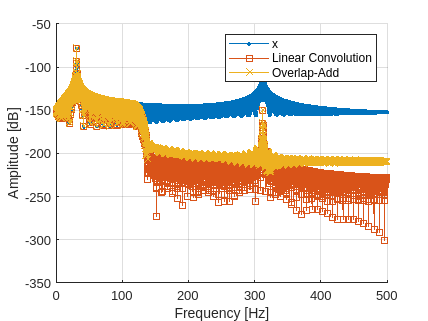


% Using 'freqz'
nFFT = 2^12; % Number of points of the fft
Xf      = freqz(x, length(x), nFFT);
Yf_L    = freqz(y_L, length(y_L), nFFT);
[Yf, w] = freqz(y, length(y), nFFT);

% Frequency normalization
w = w/pi * (Fs/2);

% Mag to dB
Xf     = mag2db(abs(Xf)/nFFT);
Yf_L   = mag2db(abs(Yf_L)/nFFT);
Yf     = mag2db(abs(Yf)/nFFT);

% Frequency Response
figure
hold on
plot(w, Xf,   '.-')
plot(w, Yf_L, 's-')
plot(w, Yf,   'x-')
hold off
grid on
legend({'x','Linear Convolution', 'Overlap-Add'})
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')

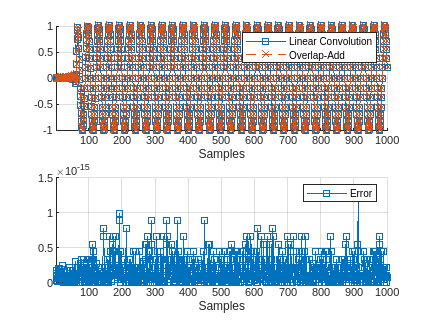


% Error between the Linear convolution and the frequency filtering
len_err = min([length(y_L),length(y)]);
error = y_L(1:len_err)-y(1:len_err);
error = abs(error);

figure;
subplot(2,1,1)
  hold on
  plot(y_L,'s-')
  plot(y,'x--')
  hold off
  xlim([1,1e3])
  legend({'Linear Convolution', 'Overlap-Add'})
  grid on
  xlabel('Samples')
subplot(2,1,2)
  hold on
  plot(error,'s-')
  hold off
  xlim([1,1e3])
  legend({'Error'})
  grid on
  xlabel('Samples')